addpath("helpers")

data_src = "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-end_side_fw_0\measurement_002";
iwr = IWR1843(data_src);
load(data_src+"\RA.mat", "-mat");
srcParts = split(data_src, "\");
dataName = join(srcParts(end-1:end), "-");
clear srcParts
[rangeBins, angleBins, numFrames] = size(DATA);

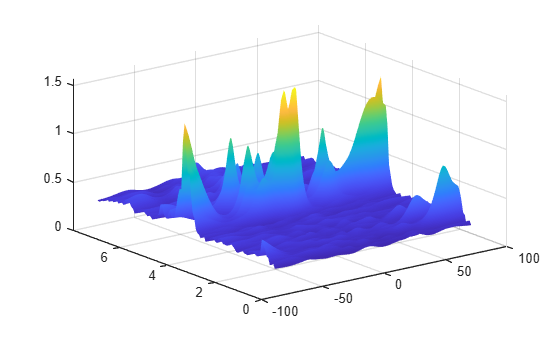

bgFilterFrameCount = 100;
showFrame=195;

% BG = bgFilter(DATA(:, :, 1), bgFilterFrameCount);
BG = bgFilter(zeros(rangeBins,angleBins), bgFilterFrameCount);

for frN = max([showFrame-BG.length 1]):showFrame-1
    BG.addSample(DATA(:, :, frN));
end
data = BG.addSampleNoBg(DATA(:, :, showFrame), 0.98);
data = DATA(:, :, showFrame);
% data(data<0) = 0;
% data=data.^2;
% mn = max([mean(data,"all") 0]);
% data(data<mn)=mn;
figure(1);
show3D(angGrid, rngGrid,data);

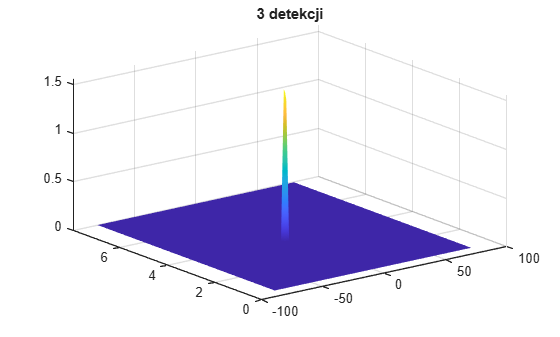

% [rangeBands angleBands]
guardCells = [4 4];
trainCells = [8 8];
fap = 2.9;
method = "GOCA";

tet=data;
[dets,mask] = runCFAR2D(guardCells,trainCells,fap,method,abs(tet));

figure(2);
plt = tet;
plt(~mask) = 0;
show3D(angGrid, rngGrid, plt);
title(num2str(size(dets,2))+" detekcji")

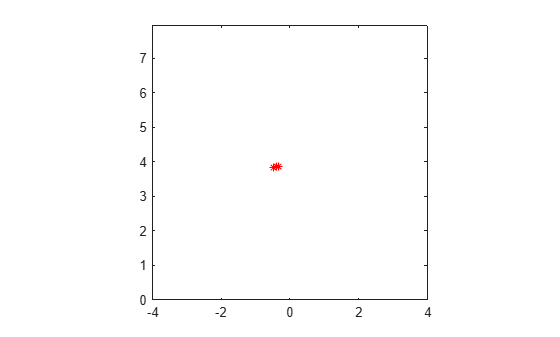


figure(3);
targets = [angGrid(dets(2, :)); rngGrid(dets(1, :))];
[X, Y] = pol2cart(deg2rad(targets(1, :)), targets(2, :));
plot(Y, X, '*',"MarkerEdgeColor","r");
ylim([0 rngGrid(end)]);
xlim([-4, 4]);
pbaspect([1 1 1]);